# Tutorial: OCT file reading and visualization

This tutorial shows how to:

- Load OCT files into MATLAB

- Visualize loaded data (fundus image, OCT slices, segmentation...)

- Generate a summary report including all relevant images.

If you need help, feel free to reach us at **dromero@mondragon.edu**

clc; clearvars; close all;
addpath(genpath('../src'));

## Read OCT files

RETIMAT supports `vol`, `e2e`, `img`, `bin` and `fda` formats.

Although the API is similar, each format has a different way of structuring the data.

In this tutorial we will work with a `vol` file. Functions to read other formats are described below

#### Spectralis (.vol)

.vol files contain a single OCT volume along with fundus image and segmentation data.

file = 'data/example_raster.vol';
[header, seg, bscan, fundus] = read_vol(file);

#### Spectralis (.e2e)

`E2E` files can contain multiple OCT volumes. They usually contain two (one per eye).

The returned objects are cell lists each related to a single OCT acquisition.

% [header, seg, bscan, fundus] = read_e2e(file);

#### Cirrus (.img/.bin)

Cirrus `img` files only contain 1 raw OCT volume and no segmentation is available.

The `read_img` function reads the B-scans in the file and tries to infer the header metadata from image size and file name.

The fundus image acquired along with the `img` is stored in a separated `bin` file

% [header,bscan] = read_img(file);

% fundus = read_bin(file);

#### Topcon (.fda)

`fda` files contain metadata, fundus, OCT and segmentation data. To read them:

% [header, seg, bscan, fundus] = read_fda(file);

## Inspect the header

The header is a structure with image metadata (fixation, scaling...).

We can display it as:

disp(header)

          fixation: 'macula'
     bscan_pattern: 'raster'
           n_ascan: 512
           n_bscan: 25
           n_axial: 496
           scale_x: 0.0124
           scale_y: 0.2650
           scale_z: 0.0039
     size_x_fundus: 768
     size_y_fundus: 768
    scale_x_fundus: 0.0124
    scale_y_fundus: 0.0124
        fov_fundus: 30
        patient_id: 'E01'
               eye: 'OD'
        scan_focus: -4.6375



Header structure is an attempt at harmonizing data from different scanners. 

Fields should be equivalent across scanners. However, due to the difficulty of fully reading propietary file formats, not all the fields will be present for every format.

In some cases a larger version of the header can be read by adding the '`full_reader'` flag

% [header, seg, bscan] = read_vol(file, 'full_header')

Similarly if we only want to read the header we can do it faster as:

% header = read_vol(file);

## Segmented boundaries

Segmentation data is stored in a struct with field names corresponding to layer boundaries.

boundaries = fields(seg);
disp(boundaries')

    {'ILM'}    {'BM'}    {'RNFL_GCL'}    {'GCL_IPL'}    {'IPL_INL'}    {'INL_OPL'}    {'OPL_ONL'}    {'ELM'}    {'MZ_EZ'}    {'OSP_IZ'}    {'IZ_RPE'}



Segmentation is measured in pixels from the top of the image.

We can plot boundary surfaces:

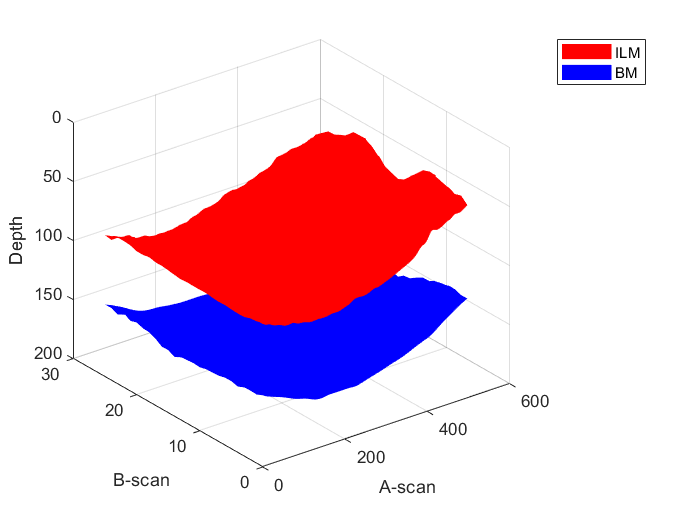

f = figure;
surf(seg.ILM, 'EdgeColor','none','FaceColor','red'); hold on;
surf(seg.BM, 'EdgeColor','none','FaceColor','blue')
set(gca,'Zdir','reverse');
legend({'ILM','BM'});
xlabel('A-scan'); ylabel('B-scan'); zlabel('Depth')

## Visualize fundus image (slo)

Often a fundus image is acquired alongside the OCT volume. Depending on the scanner this image is different:

- Spectralis: a graysacle image stored inside .vol/.e2e files.

- Cirrus: a grayscale image stored in a separated .bin file

- Topcon: a RGB color image store inside .fda files.

In any case it is useful to visualize the fundus image to inspect the fixation or detect lessions.

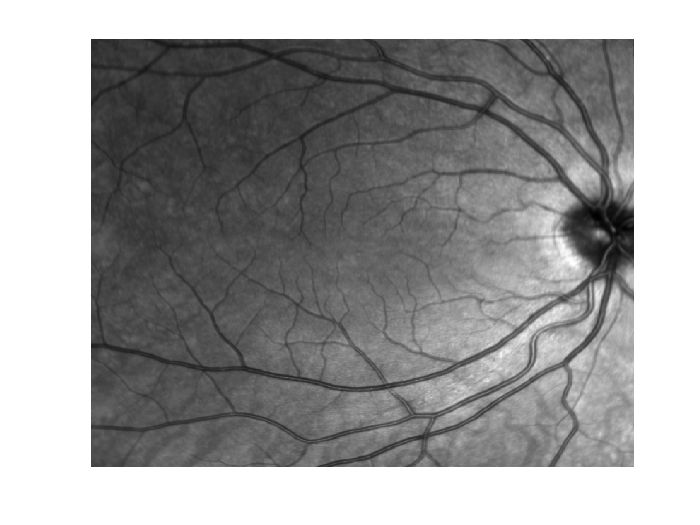

f = figure;
imagesc(fundus); colormap(gray); axis("off");

## Visualize OCT slices

Quality assurance should be a step in any image analysis pipeline. 

In the case of OCT, poor quality images, artifacts or segmentation errors are not uncommon.

Therefore, it is crucial to inspect the data to avoid those problems.

Here we plot the middle B-scan with its segmentation:

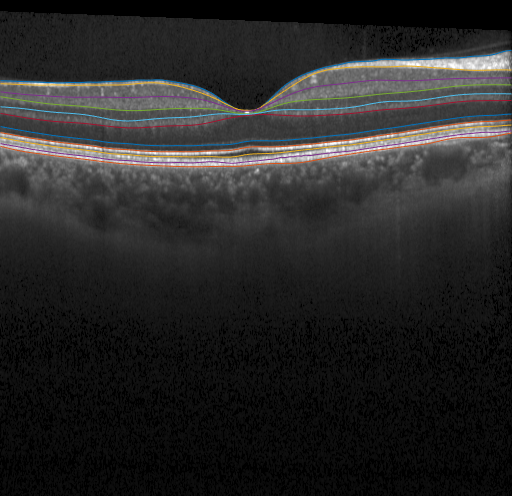

f = figure;
idx_bscan = 13;
imshow(bscan(:,:,idx_bscan)); hold on;
for j=1:length(boundaries)
    plot(seg.(boundaries{j})(idx_bscan, :))
end

## Generating a report

Doing all the previous steps separately is not convenient.

To simplify data inspection we can automatically create a summary report using the `generate_report` function

The function allows us to pass fundus,bscan and segmentation data and builds a tiled plot that can be stored in memory.

A full report includes:

- Fundus image

- Reflectance map: a 2D map obtained by averaging A-scan intensities in depth. Useful to detect noisy B-scans and shades.

- Thickness maps: 2D maps generated by computing layer thicknesses from segmentation data. Useful to detect segmentation errors or lessions.

- B-scans: several slices with overlapping segmentation.

As an example, let's generate a full report for the loaded image.

As arguments we need to provide image data and the layers for which we want to plot thickness maps

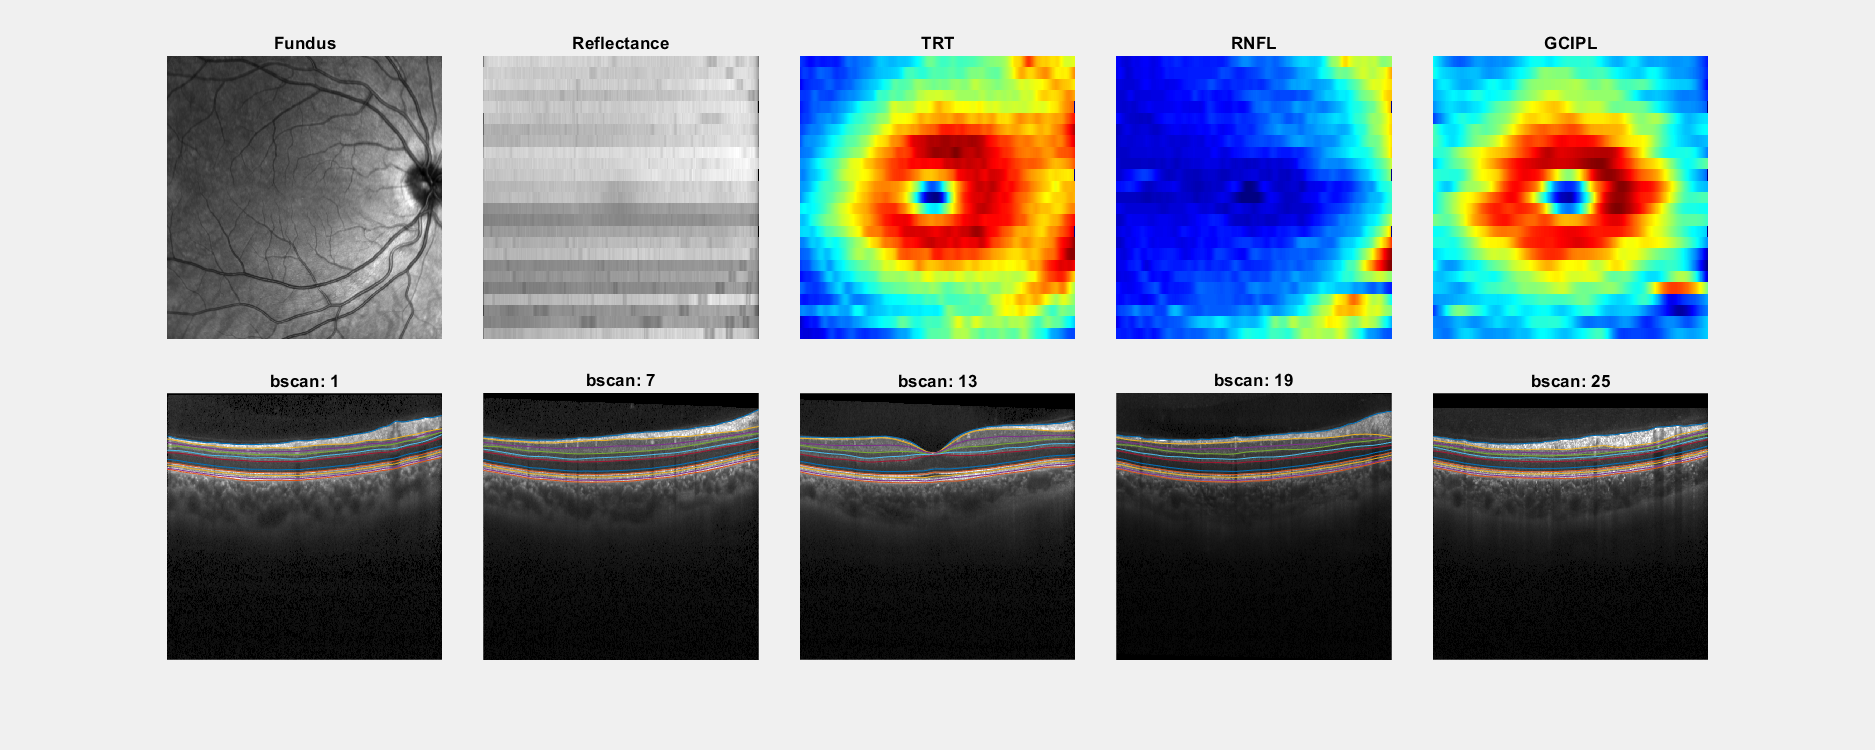

layers = {'TRT','RNFL','GCIPL'};
generate_report(bscan, seg, fundus, layers);

If we want to store it as a png withoug opening a window 

generate_report(bscan, seg, fundus, layers, 'file_name', 'report.png', 'visible', 'off');